## Preprocessing

clear
clc
close all
format compact

## Read in data

input = readtable('./Data_100k/LHS_parameters_m.txt'); % Input data parameters (31)
% (unseen)
output = readtable('./Data_100k/CellPerformance.txt'); % Output data parameters (4)
% (unseen)

## Input - Group 1 

% Define parameters for the parameter group
lt_parameters = [input.LH, input.LP, input.LE];
mo_parameters = [input.muHh, input.muPh, input.muPe, input.muEe];
bd_parameters = [input.NvH, input.NcH, input.NvE, input.NcE, input.NvP,...
    input.NcP];
ipef_parameters = [input.chiHh, input.chiHe, input.chiPh, input.chiPe,...
    input.chiEh, input.chiEe];

% Define labels for the parameters
lt_labels = {'${l}^{H}/\textrm{nm}$', '${l}^{P}/\textrm{nm}$', ...
    '${l}^{E}/\textrm{nm}$'};

mo_labels = {'${\mu}^{H}_{h}/\textrm{m}^{2}\textrm{V}^{-1}\textrm{s}^{-1}$', ...
    '${\mu}^{P}_{h}/\textrm{m}^{2}\textrm{V}^{-1}\textrm{s}^{-1}$',...
    '${\mu}^{P}_{e}/\textrm{m}^{2}\textrm{V}^{-1}\textrm{s}^{-1}$',...
    '${\mu}^{E}_{e}/\textrm{m}^{2}\textrm{V}^{-1}\textrm{s}^{-1}$'};

bd_labels = {'${N}^{H}_{v}/\textrm{m}^{-3}$',...
    '${N}^{H}_{c}/\textrm{m}^{-3}$', '${N}^{E}_{v}/\textrm{m}^{-3}$', ...
             '${N}^{E}_{c}/\textrm{m}^{-3}$',...
             '${N}^{P}_{v}/\textrm{m}^{-3}$',...
             '${N}^{P}_{c}/\textrm{m}^{-3}$'};

ipef_labels = {'${\chi}^{H}_{h}/\textrm{eV}$',...
    '${\chi}^{H}_{e}/\textrm{eV}$', '${\chi}^{P}_{h}/\textrm{eV}$', ...
               '${\chi}^{P}_{e}/\textrm{eV}$',...
               '${\chi}^{E}_{h}/\textrm{eV}$', ...
               '${\chi}^{E}_{e}/\textrm{eV}$'};

% Define labels for the processed parameter values
lt_processed_labels = {'${\hat{l}}^{H}$', '$\hat{l}^{P}$', ...
    '$\hat{l}^{E}$'};

mo_processed_labels = {'${\hat{\mu}}^{H}_{h}$', '${\hat{\mu}}^{P}_{h}$',...
    '${\hat{\mu}}^{P}_{e}$','${\hat{\mu}}^{E}_{e}$'};

bd_processed_labels = {'${\hat{N}}^{H}_{v}$', '${\hat{N}}^{H}_{c}$',...
    '${\hat{N}}^{E}_{v}$', '${\hat{N}}^{E}_{c}$', '${\hat{N}}^{P}_{v}$',...
    '${\hat{N}}^{P}_{c}$'};

ipef_processed_labels = {'${\hat{\chi}}^{H}_{h}$', '${\hat{\chi}}^{H}_{e}$',...
    '${\hat{\chi}}^{P}_{h}$', '${\hat{\chi}}^{P}_{e}$', ...
    '${\hat{\chi}}^{E}_{h}$', '${\hat{\chi}}^{E}_{e}$'};

figure();
tlo1 = tiledlayout(2,4,'TileSpacing','Compact');
% Box plot raw values of the paramedaster group
ax1 = nexttile(tlo1); 
log_and_boxplot(ax1, lt_parameters, lt_labels);
ylabel('Dimensional features');
set(gca,'fontname','Times')  % Set it to times
ax2 = nexttile(tlo1); 
log_and_boxplot(ax2, mo_parameters, mo_labels);

ax3 = nexttile(tlo1); 
log_and_boxplot(ax3, bd_parameters, bd_labels);
ax4 = nexttile(tlo1); 
log_and_boxplot(ax4, ipef_parameters, ipef_labels);

% Box plot log normalised values of the parameter group
ax5 = nexttile(tlo1); 
normalise_and_boxplot(ax5, lt_parameters, lt_processed_labels);
ylabel('Normalised dimensionless features');
set(gca,'fontname','Times')  % Set it to times
ax6 = nexttile(tlo1); 
normalise_and_boxplot(ax6, mo_parameters, mo_processed_labels);
ax7 = nexttile(tlo1); 
normalise_and_boxplot(ax7, bd_parameters, bd_processed_labels);
ax8 = nexttile(tlo1); 
normalise_and_boxplot(ax8, ipef_parameters, ipef_processed_labels);

## Input - Group 2

wf_parameters = [input.Wlm, input.Whm];
rp_parameters = [input.epsH, input.epsP, input.epsE];
acrc_parameters = [input.Gavg, input.Aug, input.Brad];
ltp_parameters = [input.Taue, input.Tauh];
rv_parameters = [input.vII, input.vIII];

wf_labels = {'${W}_{B}/\textrm{eV}$', '${W}_{F}/\textrm{eV}$'};
rp_labels = {'${\varepsilon}^{H}/1$', '${\varepsilon}^{P}/1$',...
    '${\varepsilon}^{E}/1$'};
acrc_labels = {'${G}_{avg}/\textrm{m}^{-3}\textrm{s}^{-1}$', ...
               '${A}_{(e,h)}/\textrm{m}^{6}\textrm{s}^{-1}$', ...
               '${B}_{rad}/\textrm{m}^{3}\textrm{s}^{-1}$'};
ltp_labels = {'${\tau}_{e}/\textrm{s}$', '${\tau}_{h}/\textrm{s}$'};
rv_labels = {'${v}_{II}/\textrm{m}^{4}\textrm{s}^{-1}$',...
    '${v}_{III}/\textrm{m}^{4}\textrm{s}^{-1}$'};

wf_processed_labels = {'${\hat{W}}_{B}$', '${\hat{W}}_{F}$'};
rp_processed_labels = {'${\hat{\varepsilon}}^{H}$',...
    '${\hat{\varepsilon}}^{P}$', '${\hat{\varepsilon}}^{E}$'};
acrc_processed_labels = {'${\hat{G}}_{avg}$', ...
               '${\hat{A}}_{(e,h)}$', ...
               '${\hat{B}}_{rad}$'};
ltp_processed_labels = {'${\hat{\tau}}_{e}$', '${\hat{\tau}}_{h}$'};
rv_processed_labels = {'${\hat{v}}_{II}$', '${\hat{v}}_{III}$'};
hold off;

figure();
tlo2 = tiledlayout(2,5,'TileSpacing','Compact');
ax1_2 = nexttile(tlo2); 
log_and_boxplot(ax1_2', wf_parameters, wf_labels);
ylabel('Dimensional features');
set(gca,'fontname','Times')  % Set it to times
ax2_2 = nexttile(tlo2); 
log_and_boxplot(ax2_2, rp_parameters, rp_labels);
ax3_2 = nexttile(tlo2); 
log_and_boxplot(ax3_2, acrc_parameters, acrc_labels);
ax4_2 = nexttile(tlo2); 
log_and_boxplot(ax4_2, ltp_parameters, ltp_labels);
ax5_2 = nexttile(tlo2); 
log_and_boxplot(ax5_2, rv_parameters, rv_labels);

ax6_2 = nexttile(tlo2); 
normalise_and_boxplot(ax6_2, wf_parameters, wf_processed_labels);
ylabel('Normalised dimensionless features');
set(gca,'fontname','Times')  % Set it to times
ax7_2 = nexttile(tlo2);
normalise_and_boxplot(ax7_2, rp_parameters, rp_processed_labels);
ax8_2 = nexttile(tlo2);
normalise_and_boxplot(ax8_2, acrc_parameters, acrc_processed_labels);
ax9_2 = nexttile(tlo2);
normalise_and_boxplot(ax9_2, ltp_parameters, ltp_processed_labels);
ax10_2 = nexttile(tlo2);
normalise_and_boxplot(ax10_2, rv_parameters, rv_processed_labels);

## Output

output_parameters = [output.isc, output.Voc, output.FF, output.PCE];
output_labels = {'${i}_{sc}/\textrm{A} \textrm{m}^{-2}$',...
    '${V}_{oc}/\textrm{V}$', '$\textrm{FF}/1$', '$\eta$/1'};
output_processed_labels = {'${\hat{i}}_{sc}$', '${\hat{V}}_{oc}$',...
    '$\hat{\textrm{FF}}$', '$\hat{\eta}$'};

figure();
tlo3 = tiledlayout(2,1,'TileSpacing','Compact');
ax1_3 = nexttile(tlo3); 
log_and_boxplot(ax1_3, output_parameters, output_labels);

ylabel('Dimensional outputs');
set(gca,'fontname','Times')
ax2_3 = nexttile(tlo3); 
normalise_and_boxplot(ax2_3, output_parameters, output_processed_labels);

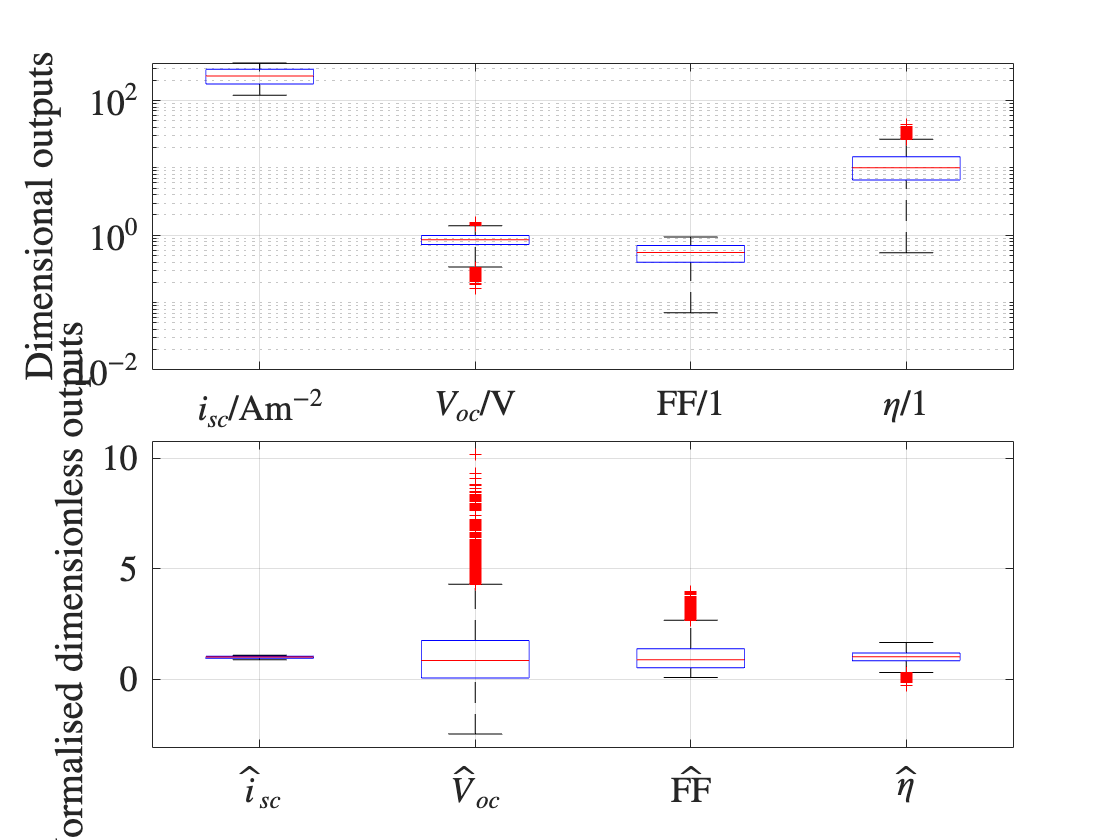

ylabel('Normalised dimensionless outputs');
set(gca,'fontname','Times')

## Spearman correlation coefficients

labels = {'LH', 'LP', 'LE', 'muHh', 'muPh', 'muPe', 'muEe', 'NvH', 'NcH',
    'NvE', 'NcE', 'NvP', 'NcP', 'chiHh', 'chiHe', 'chiPh', 'chiPe', 'chiEh', ...
    'chiEe', 'Wlm', 'Whm', 'epsH', 'epsP', 'epsE', 'Gavg', 'Aug', 'Brad', 
    'Taue', 'Tauh', 'vII', 'vIII','isc','Voc', 'FF', 'PCE'};

X_Y = [log_normalise_input(input) output.isc, output.Voc, ...
             output.FF, output.PCE];

figure(11);
r = corr(X_Y, 'type','Spearman');
h = heatmap(r);
mycolormap = customcolormap(linspace(0,1,11), ...
    {'#68011d','#b5172f','#d75f4e','#f7a580','#fedbc9','#f5f9f3','#d5e2f0', ...
    '#93c5dc','#4295c1','#2265ad','#062e61'});
colormap(h, mycolormap);
h.XDisplayLabels = labels;
h.YDisplayLabels = labels;
s = struct(h);
s.XAxis.TickLabelRotation = 90;  % vertical
h.FontSize = 12;
h.FontName = 'Times';
h.Interpreter = 'latex';

## SVM model - hyperparameter optimisation

input = readtable('./Data_10k/LHS_parameters_m.txt');
output = readtable('./Data_10k/CellPerformance.txt');
[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_svmModel = fitrsvm(X_train, Y_1_train,'KernelFunction','gaussian', ...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

Y_2_svmModel = fitrsvm(X_train, Y_2_train,'KernelFunction','gaussian', ...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

Y_3_svmModel = fitrsvm(X_train, Y_3_train,'KernelFunction','gaussian', ...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

Y_4_svmModel = fitrsvm(X_train, Y_4_train,'KernelFunction','gaussian', ...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

## SVM model - optimised models

input = readtable('./Data_100k/LHS_parameters_m.txt');
output = readtable('./Data_100k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_BoxConstraint = 990;
Y_1_KernelScale = 1.60;
Y_1_Epsilon = 0.129;
Y_1_Standardize = false;
Y_1_svmModel = fitrsvm(X_train, Y_1_train,'KernelFunction','gaussian', ...
    'BoxConstraint',Y_1_BoxConstraint,...
    'KernelScale',Y_1_KernelScale, 'Epsilon', Y_1_Epsilon, ...
    'Standardize', Y_1_Standardize)

Y_2_BoxConstraint = 758;
Y_2_KernelScale = 29.8;
Y_2_Epsilon = 0.00961;
Y_2_Standardize = true;
Y_2_svmModel = fitrsvm(X_train, Y_2_train,'KernelFunction','gaussian', ...
    'BoxConstraint',Y_2_BoxConstraint,...
    'KernelScale',Y_2_KernelScale, 'Epsilon', Y_2_Epsilon, ...
    'Standardize', Y_2_Standardize)

Y_3_BoxConstraint = 238;
Y_3_KernelScale = 2.43;
Y_3_Epsilon = 0.0221;
Y_3_Standardize = false;
Y_3_svmModel = fitrsvm(X_train, Y_3_train,'KernelFunction','gaussian', ...
    'BoxConstraint',Y_3_BoxConstraint,...
    'KernelScale',Y_3_KernelScale, 'Epsilon', Y_3_Epsilon, ...
    'Standardize', Y_3_Standardize)

Y_4_BoxConstraint = 1000;
Y_4_KernelScale = 20.4;
Y_4_Epsilon = 0.00774;
Y_4_Standardize = true;
Y_4_svmModel = fitrsvm(X_train, Y_4_train,'KernelFunction','gaussian', ...
    'BoxConstraint',Y_4_BoxConstraint,...
    'KernelScale',Y_4_KernelScale, 'Epsilon', Y_4_Epsilon, ...
    'Standardize', Y_4_Standardize)

figure(12);
evaluate_models_and_plot_result(Y_1_svmModel, Y_2_svmModel, ...
    Y_3_svmModel, Y_4_svmModel, ...
    X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test)

## Regression Tree Ensemble - hyperparameter optimisation

input = readtable('./Data_10k/LHS_parameters_m.txt');
output = readtable('./Data_10k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_ensembleModel = fitrensemble(X_train, Y_1_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))

Y_2_ensembleModel = fitrensemble(X_train, Y_2_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))

Y_3_ensembleModel = fitrensemble(X_train, Y_3_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))

Y_4_ensembleModel = fitrensemble(X_train, Y_4_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))

## Regression Tree Ensemble - optimised models

input = readtable('./Data_100k/LHS_parameters_m.txt');
output = readtable('./Data_100k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_Method = 'LSBoost';
Y_1_NumLearningCycles = 487;
Y_1_LearnRate = 0.147;
Y_1_MinLeafSize = 83;
t = templateTree('MinLeafSize', Y_1_MinLeafSize,'Reproducible',true);
Y_1_ensembleModel = fitrensemble(X_train, Y_1_train,'NumLearningCycles', ...
    Y_1_NumLearningCycles,'Learners',t,'Method',Y_1_Method,...
    'LearnRate',Y_1_LearnRate)

Y_2_Method = 'LSBoost';
Y_2_NumLearningCycles = 124;
Y_2_LearnRate = 0.336;
Y_2_MinLeafSize = 1;
t = templateTree('MinLeafSize', Y_2_MinLeafSize,'Reproducible',true);
Y_2_ensembleModel = fitrensemble(X_train, Y_2_train,'NumLearningCycles', ...
    Y_2_NumLearningCycles,'Learners',t,'Method',Y_2_Method,...
    'LearnRate',Y_2_LearnRate)

Y_3_Method = 'LSBoost';
Y_3_NumLearningCycles = 157;
Y_3_LearnRate = 0.160;
Y_3_MinLeafSize = 28;
t = templateTree('MinLeafSize', Y_3_MinLeafSize,'Reproducible',true);
Y_3_ensembleModel = fitrensemble(X_train, Y_3_train,'NumLearningCycles', ...
    Y_3_NumLearningCycles,'Learners',t,'Method',Y_3_Method,...
    'LearnRate',Y_3_LearnRate)

Y_4_Method = 'LSBoost';
Y_4_NumLearningCycles = 485;
Y_4_LearnRate = 0.196;
Y_4_MinLeafSize = 169;
t = templateTree('MinLeafSize', Y_4_MinLeafSize,'Reproducible',true);
Y_4_ensembleModel = fitrensemble(X_train, Y_4_train,'NumLearningCycles', ...
    Y_4_NumLearningCycles,'Learners',t,'Method',Y_4_Method,...
    'LearnRate',Y_4_LearnRate)

figure(13);
evaluate_models_and_plot_result(Y_1_ensembleModel, Y_2_ensembleModel, ...
    Y_3_ensembleModel, Y_4_ensembleModel, ...
    X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test)

## Gauss Process Regression - hyperparameter optimisation

input = readtable('./Data_10k/LHS_parameters_m.txt');
output = readtable('./Data_10k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_rgpModel = fitrgp(X_train,Y_1_train,'KernelFunction','squaredexponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

Y_2_rgpModel = fitrgp(X_train,Y_2_train,'KernelFunction','squaredexponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

Y_3_rgpModel = fitrgp(X_train,Y_3_train,'KernelFunction','squaredexponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

Y_4_rgpModel = fitrgp(X_train,Y_4_train,'KernelFunction','squaredexponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

## Gauss Process Regression - optimised models

input = readtable('./Data_100k/LHS_parameters_m.txt');
output = readtable('./Data_100k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_Sigma = 12.5;
Y_1_rgpModel = fitrgp(X_train, Y_1_train,'KernelFunction','squaredexponential',...
    'Standardize',true,'Sigma',Y_1_Sigma)

Y_2_Sigma = 0.0224;
Y_2_rgpModel = fitrgp(X_train, Y_2_train,'KernelFunction','squaredexponential',...
    'Standardize',true,'Sigma',Y_2_Sigma)

Y_3_Sigma = 0.0624;
Y_3_rgpModel = fitrgp(X_train, Y_3_train,'KernelFunction','squaredexponential',...
    'Standardize',true,'Sigma',Y_3_Sigma)

Y_4_Sigma = 0.810;
Y_4_rgpModel = fitrgp(X_train, Y_4_train,'KernelFunction','squaredexponential',...
    'Standardize',true,'Sigma',Y_4_Sigma)

figure(14);
evaluate_models_and_plot_result(Y_1_rgpModel, Y_2_rgpModel, Y_3_rgpModel, ...
    Y_4_rgpModel, X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test)

## GAM model for regression - hyperparameter optimisation

input = readtable('./Data_10k/LHS_parameters_m.txt');
output = readtable('./Data_10k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_rgamModel = fitrgam(X_train,Y_1_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

Y_2_rgamModel = fitrgam(X_train,Y_2_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

Y_3_rgamModel = fitrgam(X_train,Y_3_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

Y_4_rgamModel = fitrgam(X_train,Y_4_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

## **GAM model for regression - optimised models**

input = readtable('./Data_100k/LHS_parameters_m.txt');
output = readtable('./Data_100k/CellPerformance.txt');

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_InitialLearnRateForPredictors = 0.129;
Y_1_NumTreesPerPredictor = 483;
Y_1_Interactions = 18;
Y_1_InitialLearnRateForInteractions = 0.0226;
Y_1_NumTreesPerInteraction = 309;
Y_1_rgamModel = fitrgam(X_train,Y_1_train,'InitialLearnRateForInteractions', ...
    Y_1_InitialLearnRateForInteractions, 'NumTreesPerPredictor', ...
    Y_1_NumTreesPerPredictor,...
    'Interactions',Y_1_Interactions, 'InitialLearnRateForPredictors', ...
    Y_1_InitialLearnRateForPredictors,...
    'NumTreesPerInteraction',Y_1_NumTreesPerInteraction)

Y_2_InitialLearnRateForPredictors = 0.946;
Y_2_NumTreesPerPredictor = 93;
Y_2_Interactions = 41;
Y_2_InitialLearnRateForInteractions = 0.330;
Y_2_NumTreesPerInteraction = 60;
Y_2_rgamModel = fitrgam(X_train,Y_2_train,'InitialLearnRateForInteractions', ...
    Y_2_InitialLearnRateForInteractions, 'NumTreesPerPredictor', ...
    Y_2_NumTreesPerPredictor,...
    'Interactions',Y_2_Interactions, 'InitialLearnRateForPredictors', ...
    Y_2_InitialLearnRateForPredictors,...
    'NumTreesPerInteraction',Y_2_NumTreesPerInteraction)

Y_3_InitialLearnRateForPredictors = 0.553;
Y_3_NumTreesPerPredictor = 11;
Y_3_Interactions = 25;
Y_3_InitialLearnRateForInteractions = 0.0514;
Y_3_NumTreesPerInteraction = 148;
Y_3_rgamModel = fitrgam(X_train,Y_3_train,'InitialLearnRateForInteractions', ...
    Y_3_InitialLearnRateForInteractions, 'NumTreesPerPredictor', ...
    Y_3_NumTreesPerPredictor,...
    'Interactions',Y_3_Interactions, 'InitialLearnRateForPredictors', ...
    Y_3_InitialLearnRateForPredictors,...
    'NumTreesPerInteraction',Y_3_NumTreesPerInteraction)

Y_4_InitialLearnRateForPredictors = 0.194;
Y_4_NumTreesPerPredictor = 254;
Y_4_Interactions = 73;
Y_4_InitialLearnRateForInteractions = 0.0216;
Y_4_NumTreesPerInteraction = 471;
Y_4_rgamModel = fitrgam(X_train,Y_4_train,'InitialLearnRateForInteractions', ...
    Y_4_InitialLearnRateForInteractions, 'NumTreesPerPredictor', ...
    Y_4_NumTreesPerPredictor,...
    'Interactions',Y_4_Interactions, 'InitialLearnRateForPredictors', ...
    Y_4_InitialLearnRateForPredictors,...
    'NumTreesPerInteraction',Y_4_NumTreesPerInteraction)

figure(15);
evaluate_models_and_plot_result(Y_1_rgamModel, Y_2_rgamModel, Y_3_rgamModel, ...
    Y_4_rgamModel, X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test)

## Shallow Neural Network model for regression - hyperparameter optimisation + optimised model

input = readtable('./Data_100k/LHS_parameters_m.txt');
output = readtable('./Data_100k/CellPerformance.txt');
outputDir = "NN";

[X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
 X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output);

Y_1_NN = fitrnet(X_train, Y_1_train,"OptimizeHyperparameters","auto", ...
    "HyperparameterOptimizationOptions",struct("AcquisitionFunctionName", ...
    "expected-improvement-plus"))
outputFile = fullfile(outputDir, "Y_1_NN.mat");
save(outputFile, "Y_1_NN");

Y_2_NN = fitrnet(X_train, Y_2_train,"OptimizeHyperparameters","auto", ...
    "HyperparameterOptimizationOptions",struct("AcquisitionFunctionName", ...
    "expected-improvement-plus"))
outputFile = fullfile(outputDir, "Y_2_NN.mat");
save(outputFile, "Y_2_NN");

Y_3_NN = fitrnet(X_train, Y_3_train,"OptimizeHyperparameters","auto", ...
    "HyperparameterOptimizationOptions",struct("AcquisitionFunctionName", ...
    "expected-improvement-plus"))
outputFile = fullfile(outputDir, "Y_3_NN.mat");
save(outputFile, "Y_3_NN");

Y_4_NN = fitrnet(X_train, Y_4_train,"OptimizeHyperparameters","auto", ...
    "HyperparameterOptimizationOptions",struct("AcquisitionFunctionName", ...
    "expected-improvement-plus"))
outputFile = fullfile(outputDir, "Y_4_NN.mat");
save(outputFile, "Y_4_NN");

figure(16);
evaluate_models_and_plot_result(Y_1_NN, Y_2_NN, Y_3_NN, ...
    Y_4_NN, X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test)

## Shallow NN model plot info + SHAP analysis

figure(17);
iteration = Y_4_NN.TrainingHistory.Iteration;
trainLosses = Y_4_NN.TrainingHistory.TrainingLoss;
semilogy(iteration,trainLosses)
legend(["Training","Validation"])
xlabel("Iteration")
ylabel("Mean Squared Error")
figure(18);

[background_idx, compute_idx] = dividerand(size(input,1), 0.02, 0.10);

explainer = shapley(Y_4_NN, X(background_idx, :), 'QueryPoint', ...
    X(compute_idx, :), 'MaxNumSubsets', 2^5)

save('explainer.NN', 'explainer')

figure();
plot(explainer);

figure();
swarmchart(explainer,NumImportantPredictors=10, ...
    ColorMap='bluered');

## SHAP values top 4 performers

[mx,ind]=maxk(table2array(output(:,"PCE")),4);

X = log_normalise_input(input);

explainer1 = shapley(Y_4_NN,'QueryPoint', X(ind(1),:), ...
    'UseParallel',true,'MaxNumSubsets',2^5)
explainer2 = shapley(Y_4_NN,'QueryPoint', X(ind(2),:), ...
    'UseParallel',true,'MaxNumSubsets',2^5)
explainer3 = shapley(Y_4_NN,'QueryPoint', X(ind(3),:), ...
    'UseParallel',true,'MaxNumSubsets',2^5)
explainer4 = shapley(Y_4_NN,'QueryPoint', X(ind(4),:), ...
    'UseParallel',true,'MaxNumSubsets',2^5)

figure();
subplot(2,2,1);
plot(explainer1);
hold on;
subplot(2,2,2);
plot(explainer2);
hold on;
subplot(2,2,3);
plot(explainer3);
hold on;
subplot(2,2,4);
plot(explainer4);
hold off;

## Parallel Coordinates Plot

figure();

input_and_PCE = [input, output(:,"PCE")];
features_to_display = {'Gavg','LP','vIII', 'muPh', 'muPe', 'vII',...
    'Whm', 'NcE', 'muHh', 'chiPe', 'PCE'};
[mx,ind]=maxk(table2array(input_and_PCE(:,"PCE")),500);

PCEbinEdges = [25 30 35 60];
PCECategory = discretize(flip(table2array(input_and_PCE(ind,"PCE")),1),...
    PCEbinEdges, 'categorical');

p = parallelplot(table2array(flip(input_and_PCE(ind,features_to_display)),1),...
    'GroupData', PCECategory, 'Color', {'#F4538A','#F5DD61','#59D5E0'},...
    'LineWidth', [0.5 0.5 1.0], 'LineAlpha', [0.30 0.30 1], ...
    'FontSize', 16, 'DataNormalization', 'range');

S=struct(p);
S.Axes.TickLabelInterpreter='latex';
S.Axes.FontSize = 20;
S.Axes.XTickLabel = {'$G_{avg}$','${l}^{P}$', '$v_{III}$',...
    '${\mu}^{P}_{h}$', '${\mu}^{P}_{e}$', '$v_{II}$', '${W}_{F}$',...
    '${N}^{E}_{c}$', '${\mu}^{H}_{h}$', '${\chi}^{P}_{e}$', '$\eta$'};

## Estimate time NN takes to predict Y from full input dataset

clear
clc
close all

input = readtable('./Data_100k/LHS_parameters_m.txt');
output = readtable('./Data_100k/CellPerformance.txt');

X = log_normalise_input(input);

load('NN/Y_1_NN.mat')
load('NN/Y_2_NN.mat')
load('NN/Y_3_NN.mat')
load('NN/Y_4_NN.mat')

Y_1 = output.isc;
Y_2 = output.Voc;
Y_3 = output.FF;
Y_4 = output.PCE;

predict_Y_1 = @()  predict(Y_1_NN, X);
predict_Y_2 = @()  predict(Y_2_NN, X);
predict_Y_3 = @()  predict(Y_3_NN, X);
predict_Y_4 = @()  predict(Y_4_NN, X);

t1 = timeit(predict_Y_1);
t2 = timeit(predict_Y_2);
t3 = timeit(predict_Y_3);
t4 = timeit(predict_Y_4);

display(t1);
display(t2);
display(t3);
display(t4);

## Performance comparison between computing FF from predicted iSC , VOC and η vs predicting FF from NN model

input = readtable('./Data_100k/LHS_parameters_m.txt'); % Input data parameters 
% (31) (unseen)
output = readtable('./Data_100k/CellPerformance.txt');

X = log_normalise_input(input);

load('NN/Y_1_NN.mat')
load('NN/Y_2_NN.mat')
load('NN/Y_3_NN.mat')
load('NN/Y_4_NN.mat')

isc_predicted = predict(Y_1_NN, X);
Voc_predicted = predict(Y_2_NN, X);
PCE_predicted = predict(Y_4_NN, X);
Y_3_predicted = predict(Y_3_NN, X);

FF_predicted = rdivide(PCE_predicted.*10,...
   isc_predicted.*Voc_predicted);
FF_actual = table2array(output(:,"FF"));

FF_mse = mean((FF_predicted - FF_actual).^2);
FF_rmse = sqrt(FF_mse);
FF_r2 = 1 - sum((FF_predicted - FF_actual).^2)/sum((FF_actual ...
    - mean(FF_actual)).^2);

% Display the results
disp("FF computed from isc, Voc and PCE result")
disp(['Mean Squared Error: ' num2str(FF_mse)]);
disp(['Root Mean Squared Error: ' num2str(FF_rmse)]);
disp(['R^2: ' num2str(FF_r2)]);

subplot(1,2,1);
scatter(FF_actual, FF_predicted, 'filled', 'SizeData', 4);
hold on;

% Plot a diagonal line for reference (perfect prediction)
plot(FF_actual, FF_actual, 'r--','LineWidth',1);
xlim tight;
xlabel('Actual $\textrm{FF}/\textrm{1}$','Interpreter','latex');
ylabel('Predicted $\textrm{FF}/\textrm{1}$','Interpreter','latex');
title('(a)');
box on;
hold 

Y_3_mse = mean((Y_3_predicted - FF_actual).^2); % Mean Squared Error
Y_3_rmse = sqrt(Y_3_mse);
Y_3_r2 = 1 - sum((Y_3_predicted - FF_actual).^2)/sum((FF_actual ...
    - mean(FF_actual)).^2);

% Display the results
disp("FF from NN model result")
disp(['Mean Squared Error: ' num2str(Y_3_mse)]);
disp(['Root Mean Squared Error: ' num2str(Y_3_rmse)]);
disp(['R^2: ' num2str(Y_3_r2)]);

subplot(1,2,2);
scatter(FF_actual, Y_3_predicted, 'filled', 'SizeData', 4);
hold on;
% Plot a diagonal line for reference (perfect prediction)
plot(FF_actual, FF_actual, 'r--','LineWidth',1);
xlabel('Actual $\textrm{FF}/\textrm{1}$','Interpreter','latex');
ylabel('Predicted $\textrm{FF}/\textrm{1}$','Interpreter','latex');
title('(b)');

## Helper functions

function normalised = log_normalise(x)
    % Apply logarithmic transformation
    normalised = log(x)/mean(log(x));

    % Alternative approach:
    % normalised = log(x / mean(x));
    % normalised = normalised + (1-mean(normalised));
    
end

function [] = evaluate_models_and_plot_result(Y_1_model, ...
    Y_2_model, Y_3_model, Y_4_model, X_test, Y_1_test, ...
    Y_2_test, Y_3_test, Y_4_test)
            % Predict labels for the test data
    Y_1_predicted = predict(Y_1_model, X_test);
    Y_2_predicted = predict(Y_2_model, X_test);
    Y_3_predicted = predict(Y_3_model, X_test);
    Y_4_predicted = predict(Y_4_model, X_test);
    
    % Evaluate the model (you can use different evaluation metrics based 
    % on your requirements)
    Y_1_mse = mean((Y_1_predicted - Y_1_test).^2); % Mean Squared Error
    Y_1_rmse = sqrt(Y_1_mse);
    
    Y_2_mse = mean((Y_2_predicted - Y_2_test).^2); % Mean Squared Error
    Y_2_rmse = sqrt(Y_2_mse);
    
    Y_3_mse = mean((Y_3_predicted - Y_3_test).^2); % Mean Squared Error
    Y_3_rmse = sqrt(Y_3_mse);
    
    Y_4_mse = mean((Y_4_predicted - Y_4_test).^2); % Mean Squared Error
    Y_4_rmse = sqrt(Y_4_mse);
    
    Y_1_r2 = 1 - sum((Y_1_predicted - Y_1_test).^2)/sum((Y_1_test ...
        - mean(Y_1_test)).^2);
    Y_2_r2 = 1 - sum((Y_2_predicted - Y_2_test).^2)/sum((Y_2_test ...
        - mean(Y_2_test)).^2);
    Y_3_r2 = 1 - sum((Y_3_predicted - Y_3_test).^2)/sum((Y_3_test ...
        - mean(Y_3_test)).^2);
    Y_4_r2 = 1 - sum((Y_4_predicted - Y_4_test).^2)/sum((Y_4_test ...
        - mean(Y_4_test)).^2);
    
    % Display the results
    disp("Y_1 result")
    disp(['Mean Squared Error: ' num2str(Y_1_mse)]);
    disp(['Root Mean Squared Error: ' num2str(Y_1_rmse)]);
    disp(['R^2: ' num2str(Y_1_r2)]);
    
    disp("Y_2 result")
    disp(['Mean Squared Error: ' num2str(Y_2_mse)]);
    disp(['Root Mean Squared Error: ' num2str(Y_2_rmse)]);
    disp(['R^2: ' num2str(Y_2_r2)]);
    disp("Y_3 result")
    disp(['Mean Squared Error: ' num2str(Y_3_mse)]);
    disp(['Root Mean Squared Error: ' num2str(Y_3_rmse)]);
    disp(['R^2: ' num2str(Y_3_r2)]);
    disp("Y_4 result")
    disp(['Mean Squared Error: ' num2str(Y_4_mse)]);
    disp(['Root Mean Squared Error: ' num2str(Y_4_rmse)]);
    disp(['R^2: ' num2str(Y_4_r2)]);

    subplot(2,2,1);
    scatter(Y_1_test, Y_1_predicted, 'filled', 'SizeData', 4);
    hold on;
    % Plot a diagonal line for reference (perfect prediction)
    xlim = get(gca, 'XLim');
    plot(Y_1_test, Y_1_test, 'r--','LineWidth',1, 'displayname', ...
        sprintf('R^2 = 0.2%f, RMSE = 0.2f', Y_1_r2, Y_1_rmse));
    
    xlabel('Actual Values ');
    ylabel('Predicted Values');
    
    title('(a)');
    hold off;
    
    subplot(2,2,2);
    scatter(Y_2_test, Y_2_predicted, 'filled', 'SizeData', 4);
    hold on;
    % Plot a diagonal line for reference (perfect prediction)
    xlim = get(gca, 'XLim');
    plot(Y_2_test, Y_2_test, 'r--','LineWidth',1);
    sprintf('R^2 = 0.2%f, RMSE = 0.2f', Y_2_r2, Y_2_rmse);
    xlabel('Actual Values ');
    ylabel('Predicted Values');
    title('(b)');
    hold off;
    
    subplot(2,2,3);
    scatter(Y_3_test, Y_3_predicted, 'filled', 'SizeData', 4);
    hold on;
    % Plot a diagonal line for reference (perfect prediction)
    xlim = get(gca, 'XLim');
    plot(Y_3_test, Y_3_test, 'r--','LineWidth',1);
    sprintf('R^2 = 0.2%f, RMSE = 0.2f', Y_3_r2, Y_3_rmse);
    xlabel('Actual Values ');
    ylabel('Predicted Values');
    title('(c)');
    hold off;

    subplot(2,2,4);
    scatter(Y_4_test, Y_4_predicted, 'filled', 'SizeData', 4);
    hold on;
    % Plot a diagonal line for reference (perfect prediction)
    xlim = get(gca, 'XLim');
    plot(Y_4_test, Y_4_test, 'r--','LineWidth',1);
    sprintf('R^2 = 0.2%f, RMSE = 0.2f', Y_4_r2, Y_4_rmse);
    xlabel('Actual Values ');
    ylabel('Predicted Values');
    title('(d)');
    hold off;
end

function normal_X = log_normalise_input(input)
    normal_X = [log_normalise(input.LH), log_normalise(input.LP), ...
                log_normalise(input.LE), log_normalise(input.muHh), ...
                log_normalise(input.muPh), log_normalise(input.muPe), ...
                log_normalise(input.muEe), log_normalise(input.NvH), ...
                log_normalise(input.NcH), log_normalise(input.NvE), ...
                log_normalise(input.NcE), log_normalise(input.NvP), ...
                log_normalise(input.NcP), log_normalise(input.chiHh), ...
                log_normalise(input.chiHe), log_normalise(input.chiPh), ...
                log_normalise(input.chiPe), log_normalise(input.chiEh), ...
                log_normalise(input.chiEe), log_normalise(input.Wlm), ...
                log_normalise(input.Whm), log_normalise(input.epsH), ...
                log_normalise(input.epsP),log_normalise(input.epsE), ... 
                log_normalise(input.Gavg), log_normalise(input.Aug), ...
                log_normalise(input.Brad), log_normalise(input.Taue), ...
                log_normalise(input.Tauh), log_normalise(input.vII), ...
                log_normalise(input.vIII)];
end
function [X_train, Y_1_train, Y_2_train, Y_3_train, Y_4_train, ...
          X_test, Y_1_test, Y_2_test, Y_3_test, Y_4_test] = get_train_and_test_datasets(input, output)
    
    X = log_normalise_input(input);
    Y_1 = output.isc;
    Y_2 = output.Voc;
    Y_3 = output.FF;
    Y_4 = output.PCE;
    
    % randomly select indexes to split data into 80% 
    % training set, 0% validation set and 20% test set.
    [train_idx, ~, test_idx] = dividerand(size(input,1), 0.8, 0, 0.2);
    
    X_train = X(train_idx, :);
    Y_1_train = Y_1(train_idx, :);
    Y_2_train = Y_2(train_idx, :);
    Y_3_train = Y_3(train_idx, :);
    Y_4_train = Y_4(train_idx, :);
    
    X_test = X(test_idx, :);
    Y_1_test = Y_1(test_idx, :);
    Y_2_test = Y_2(test_idx, :);
    Y_3_test = Y_3(test_idx, :);
    Y_4_test = Y_4(test_idx, :);
end

function [] = boxplot_parameter_group(ax, parameters, x_labels, y_label)
    % Do a boxplot of the parameter group
    boxplot(ax, parameters, 'Labels', x_labels);
    set(gca, 'TickLabelInterpreter', 'latex');
    set(gca,'FontSize', 18);
    % ylabel(y_label, 'FontSize', 12);
    grid on;
end

function [] = log_and_boxplot(ax, parameters, x_labels)
    y_label = 'raw values';
    boxplot_parameter_group(ax, parameters, x_labels, y_label)
    set(gca, 'YScale', 'log');
    set(gca,'fontname','Times')  % Set it to times
end

function [] = normalise_and_boxplot(ax, parameters, x_labels)
    for i=1:size(parameters, 2) % Apply log-normalisation for 
        % each parameter separately
        parameters(:, i) = log_normalise(parameters(:, i));
    end
    
    y_label = 'log-normalized values';
    boxplot_parameter_group(ax, parameters, x_labels, y_label)
end